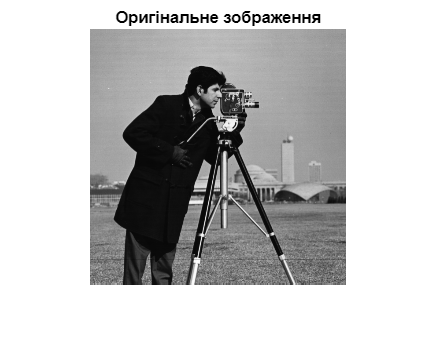

 clear, close all

% 1. Завантажив зображення з бібліотеки
a = imread('cameraman.tif');

% 2. Відобразив вихідні зображення
figure, imshow(a), title('Оригінальне зображення');

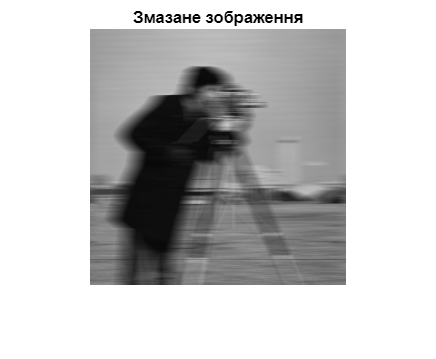

% 3-4. Здійснив процедуру перекручення зображення та відобразив
figure
LEN = 21;
THETA = 0;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(a, PSF, 'conv', 'circular');
figure, imshow(blurred), title('Змазане зображення');

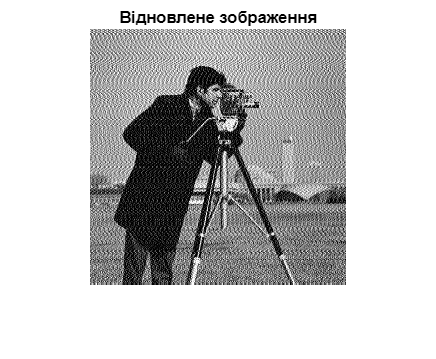

% 5-6. Виконав процедуру відновлення зображення та відобразив.
wnr1 = deconvwnr(blurred, PSF, 0);
figure, imshow(wnr1), title('Відновлене зображення');

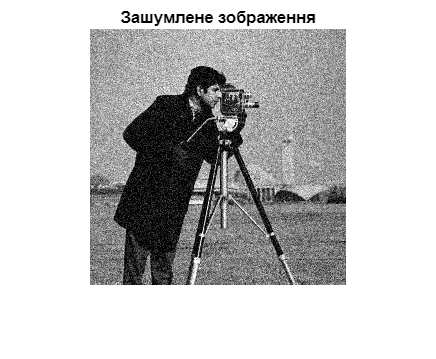

% 7. Виконав зашумлення початкового зображення та повторив пункти 2-6.
noise_a = imnoise(a, "gaussian");
PSF = fspecial('motion', LEN, THETA);
blurred_n = imfilter(noise_a, PSF, 'conv', 'circular');
wnr1_n = deconvwnr(blurred_n, PSF, 0);
figure, imshow(noise_a), title('Зашумлене зображення');

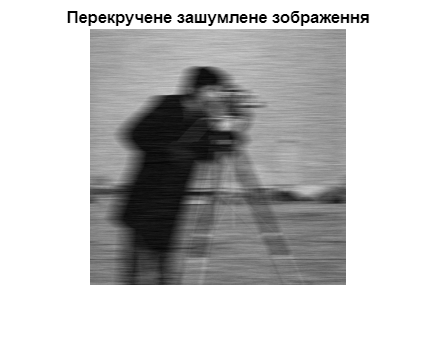

figure, imshow(blurred_n), title('Перекручене зашумлене зображення');

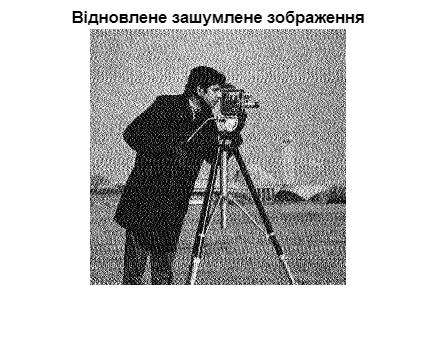

figure, imshow(wnr1_n), title('Відновлене зашумлене зображення');